## Question 2

clear all;
close all;
clc;

#### part a: Dataset

%declaring constants
N = 6;
lambda = [0 10^(-6) 0.01 0.1];

% x values with uniform distribution.
x = rand(N,1);
n = normrnd(0,sqrt(3),[N,1]);
t = (2*x-3)+n;

#### part b: fifth order polynomial

X=zeros(N);
for i = 1:6
    X(:,i) = x.^(i-1);
end

w_hat = zeros(N, length(lambda));

%training weights
for i = 1:4
    w_hat(:,i) = ((X'*X + N*lambda(i)*eye(6))^(-1))*X'*t;
end

%testing weights
plotx = [0:0.001:1]';
plotX = zeros(length(plotx), N);
for i = 1:6
    plotX(:,i) = plotx.^(i-1);
end

t_hat = plotX*w_hat;

#### Plots

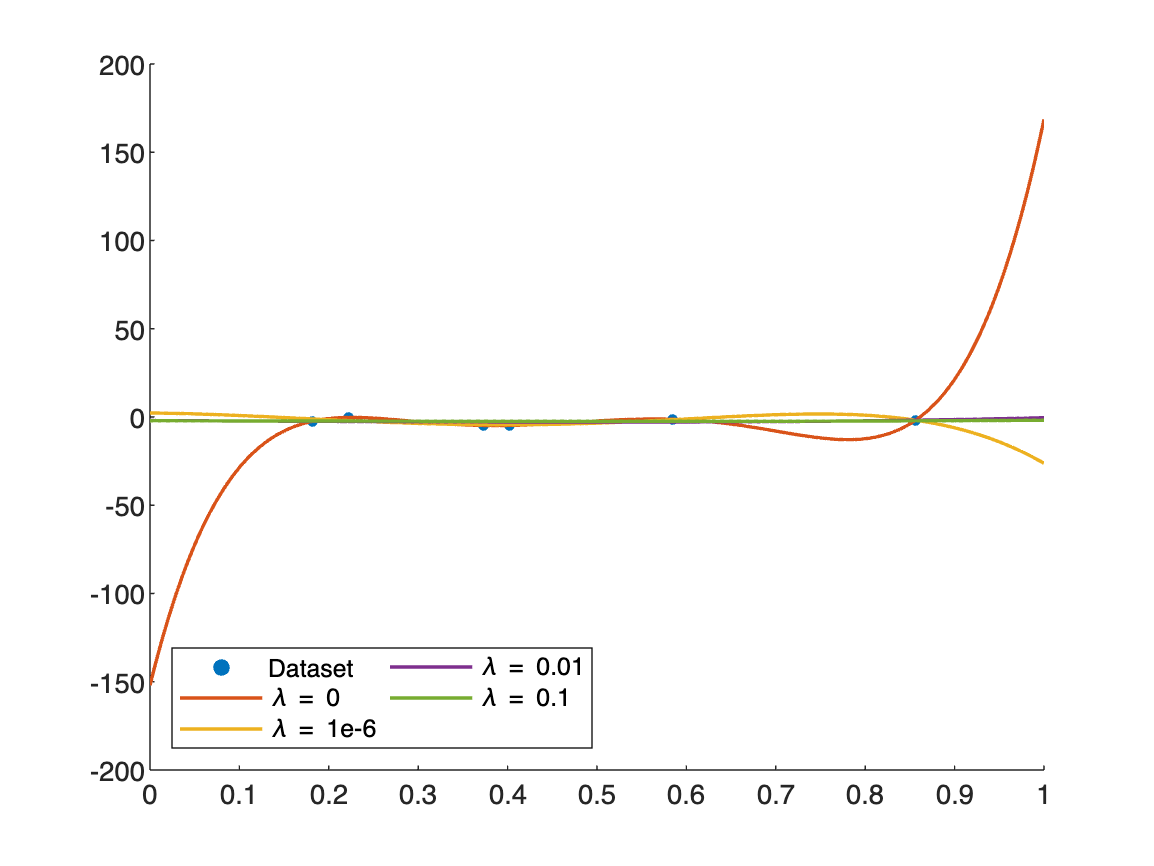

hold on;
scatter(x,t,15,'filled')
plot(plotx, t_hat, 'LineWidth',1.25)
legend({'Dataset','\lambda = 0', '\lambda = 1e-6', '\lambda = 0.01', '\lambda = 0.1'}, ...
    'Location','southwest','NumColumns',2)